clc; clearvars; close all;
% Generate data set with mixture pdf
% p(x)=p(x|j=1)P1+p(x|j=2)P2+p(x|j=3)P3 ; d=2;
J=3; % Mixture number

## Parameters

m1=[1;1]; m2=[3; 3]; m3=[2; 6];
m=[m1 m2 m3];
S1=[0.1  0; 0  0.1];
S2=[0.2  0; 0  0.2];
S3=[0.3  0; 0  0.3];
S(:,:,1)=S1; S(:,:,2)=S2; S(:,:,3)=S3; 
P1=0.4; P2=0.4; P3=0.2;
P=[P1 P2 P3];
N=500;

## Generate Data Set

sed=0;
[X,y]=mixt_model(m,S,P,N,sed);

## Display data set and means

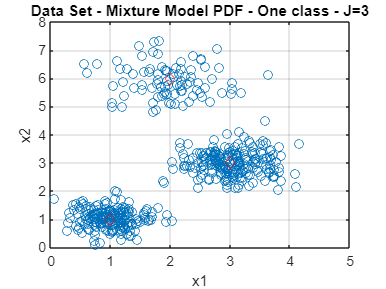

plot(X(1,:), X(2,:), 'o', m(1,1),m(2,1),'r d',m(1,2),m(2,2),'r d',m(1,3),m(2,3),'r d'  )
title(['Data Set - Mixture Model PDF - One class - J=' num2str(J)]);
xlabel('x1');ylabel('x2');grid on;

## Mixture pdf Estimate

Initial Parameters 

m1_ini=[0;2]; m2_ini=[5; 2]; m3_ini=[5; 5];
m_ini=[m1_ini m2_ini m3_ini];
s_ini=[0.15  0.27  0.4];  %Supuesto que la Si= sigma^2*I ; s_ini contiene solo sigma^2
P1_ini=1/3; P2_ini=1/3; P3_ini=1/3;
P_ini=[P1_ini P2_ini P3_ini];
e_min=10^(-5);
% estimate the mixure pdf parameters
[m_est, s_est, P_est, iter, Q_total, e_total]=...
    em_alg_function(X,m_ini, s_ini, P_ini, e_min);
%

## Display

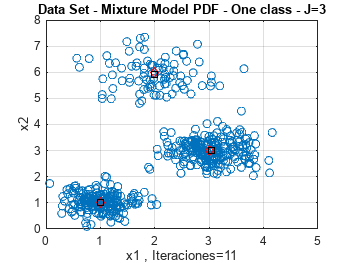

hold on; 
plot(m_est(1,1),m_est(1,2),'k s',m_est(2,1),m_est(2,2),'k s',m_est(3,1),m_est(3,2),'k s'  )
xlabel(['x1 , Iteraciones='  num2str(iter)])

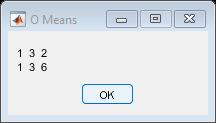


%Display means vectors, Covariance Matrices and A priori probability ORIGINALS
msgbox(num2str(m),'O Means')

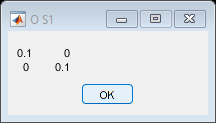

msgbox(num2str(S1),'O S1')

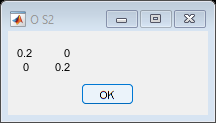

msgbox(num2str(S2),'O S2')

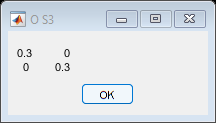

msgbox(num2str(S3), 'O S3')

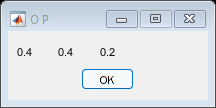

msgbox(num2str(P), 'O P')

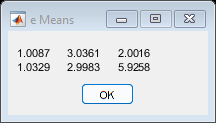


%Display means vectors and Covariance Matrices Estimated
msgbox(num2str(m_est'),'e Means')

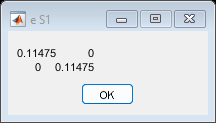

msgbox(num2str(s_est(1)*eye(2)),'e S1')

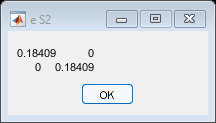

msgbox(num2str(s_est(2)*eye(2)),'e S2')

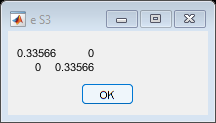

msgbox(num2str(s_est(3)*eye(2)),'e S3')

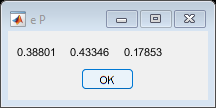

msgbox(num2str(P_est), 'e P')



%close all hidden